# Fitting a Ridge Regression Model

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and plots the data.

data = readtable("data\dataRidge.xlsx", Sheet="data");
XTrain = readtable("data\dataRidge.xlsx", Sheet="XTrain");
XTest = readtable("data\dataRidge.xlsx", Sheet="XTest");
yTrain = readtable("data\dataRidge.xlsx", Sheet="yTrain");
yTest = readtable("data\dataRidge.xlsx", Sheet="yTest");
whos data XTrain XTest yTrain yTest

  Name          Size            Bytes  Class    Attributes

  XTest        60x2              2151  table              
  XTrain      140x2              3431  table              
  data        200x3              6201  table              
  yTest        60x1              1457  table              
  yTrain      140x1              2097  table              



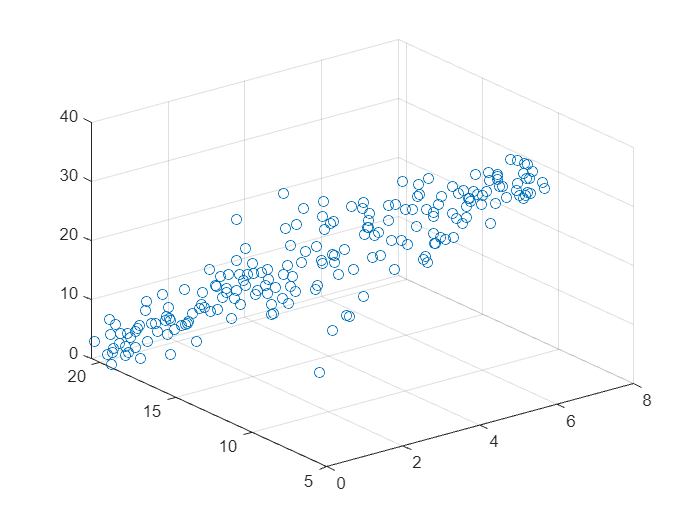

scatter3(data.X1, data.X2, data.Y)

## Task 1

Training data is saved in `XTrain` and `yTrain`.

The `ridge` function takes the data and a vector of values for λ as inputs:

`lambda` `=` `0``:``10``;`

`coef` `=` `ridge``(``y``,``X``,``lambda``)``;`

Setting the `scaled` flag to `0` returns the coefficients in the scale of the original data.

`coef` `=` `ridge``(``y``,``X``,``lambda``,``0``)``;`

lambda = 0:100;
b = ridge(yTrain.Y, table2array(XTrain), lambda, 0);

## Task 2

The output `b` is a matrix where each column is a vector of coefficients for the corresponding value of `lambda`.

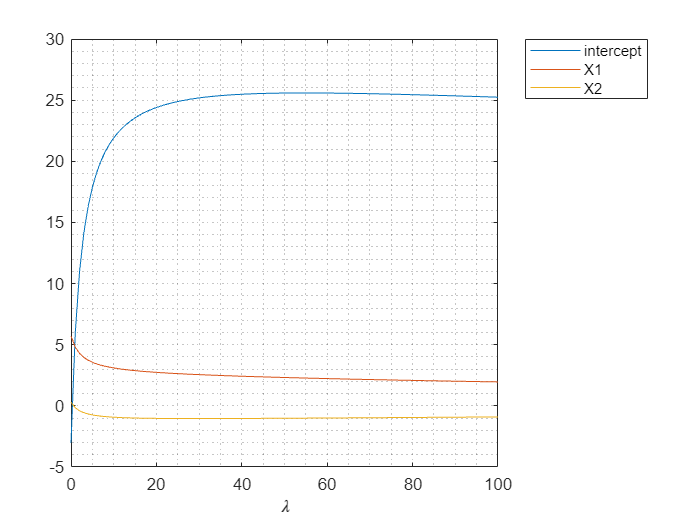

plot(lambda, b)
grid minor
legend("intercept", "X1", "X2")
xlabel("\lambda")

## Task 3

Notice that the coefficient of X2 is positive when λ is zero, and becomes negative as λ increases.

You can calculate the predicted response for each λ. The first row of the coefficient matrix corresponds to the intercept. Matrix multiply the predictor matrix and rows `2:``end` of the coefficient matrix, then add the intercept to the result.

`yp = dataNew*coef(2:``end``,:) + coef(1,:)`

yPred = b(1, :) + table2array(XTest)*b(2:end, :);

## Task 4

You can calculate the mean squared error by subtracting the actual and predicted responses, squaring each value, and taking the mean.

`err` `=` `y` `-` `yp`

`MSE` `=` `mean``(``err``.^``2``)`

The result is a row vector of the mean squared error for each parameter in the vector `lambda`.

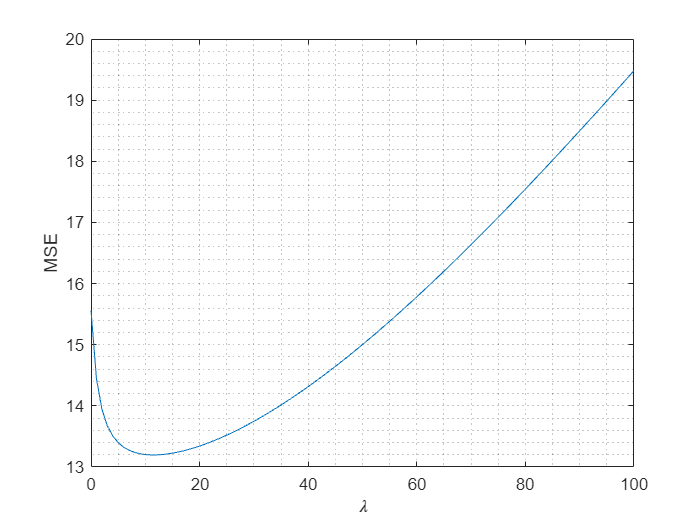

err = yPred - yTest.Y;
mdlMSE = mean(err.^2);
plot(lambda, mdlMSE)
grid minor
xlabel("\lambda")
ylabel("MSE")

## Task 5

Find smallest MSE

[minMSE, idx] = min(mdlMSE)

minMSE = 13.1974

idx = 12